# AP_PitchController.cpp

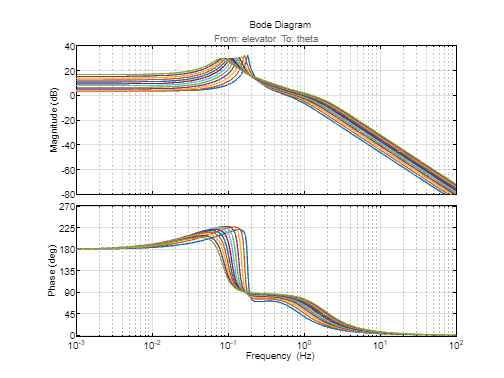

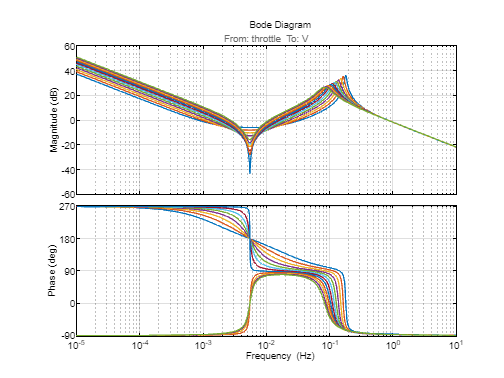

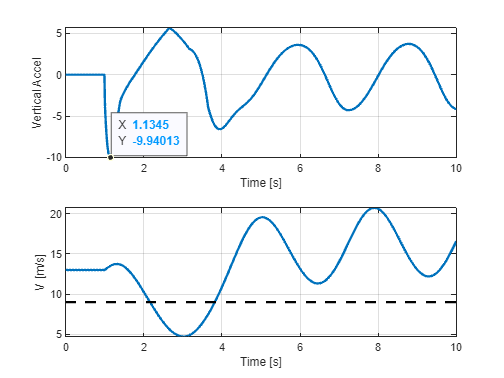

TECSinit;

## Parâmetros da Arquitetura do Controlador

Pitch.tau           = 0.01;
Pitch.rmax_pos      = 0;
Pitch.rmax_neg      = 0;
Pitch.roll_ff       = 1;
Pitch.rate_p        = 2.36887496866175*0.1;
Pitch.rate_i        = 5.67956530206951*0.1;
Pitch.rate_imax     = 1;
Pitch.rate_d        = 0.0123277335803134*2;
Pitch.rate_ff       = 3;
Pitch.rate_fltt     = 1;
Pitch.rate_flte     = 1;
Pitch.rate_fltd     = 1;
Pitch.rate_smax     = 1;
Pitch.rate_pdmx     = 1;
Pitch.rate_d_ff     = 0.01;
Pitch.rate_ntf      = 1;
Pitch.rate_nef      = 1;
Pitch.ControlRate   = 400;


# Especificação de Resposta em Frequência

In general, the goal of an aircraft control system design should be to produce dom�inant closed-loop poles that resemble the basic rigid-body poles, with satisfactory damping and natural frequency. The effect of the additional dynamics resulting from the control system compensation networks, and possibly the lower-frequency flexible modes, can be allowed for by determining an “equivalent low-order system” (Craig and Ashkenas, 1971; Hodgkinson, 1979; Bischoff, 1981; Gentry, 1982).

G_lon = SteadyState(13).G_lon;
damp(G_lon)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.49e-15                 1.00e+00       8.49e-15         1.18e+14    
 -6.89e-02 + 7.94e-01i     8.65e-02       7.97e-01         1.45e+01    
 -6.89e-02 - 7.94e-01i     8.65e-02       7.97e-01         1.45e+01    
 -5.39e+00 + 4.98e+00i     7.35e-01       7.33e+00         1.86e-01    
 -5.39e+00 - 4.98e+00i     7.35e-01       7.33e+00         1.86e-01    


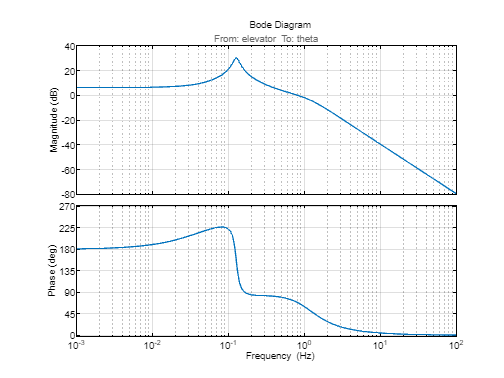

figure()
bode(G_lon(4,2),opt)

tf(G_lon(4,2))

ans =
 
  From input "elevator" to output "theta":
          -42.23 s^3 - 237.4 s^2 - 71.56 s - 6.082e-13
  -------------------------------------------------------------
  s^5 + 10.91 s^4 + 55.91 s^3 + 14.26 s^2 + 34.18 s + 2.903e-13
 
Continuous-time transfer function.
Model Properties


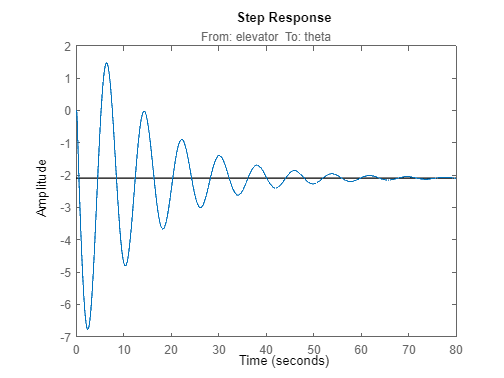

step(G_lon(4,2))

stepinfo(G_lon(4,2))

ans = struct with fields:
         RiseTime: 0.3578
    TransientTime: 58.2594
     SettlingTime: 70.2142
      SettlingMin: -6.7783
      SettlingMax: 1.4730
        Overshoot: 223.5807
       Undershoot: 70.3195
             Peak: 6.7783
         PeakTime: 2.3759


# Definição 

Gpitch = linearize('PitchHarness')

Gpitch =
 
  A = 
                elevator_CA            u            v            w           Ze            p            q            r          phi        theta   error_last  target_last   integrator
   elevator_CA            0    3.199e-54    4.036e-82    1.546e-55            0            0         10.1            0   -4.632e-26         1710        9.862            4           -1
   u             -1.049e-05       0.9996    3.369e-30     0.001468   -5.027e-07   -3.167e-33    -0.001721    4.075e-30    7.874e-32     -0.02448            0            0            0
   v             -4.182e-33   -3.407e-30        1.001    3.264e-31   -2.569e-35     0.001256   -4.446e-32     -0.03348       0.0245   -2.049e-30            0            0            0
   w             -0.0004628    -0.003021   -9.396e-31        0.985    -5.22e-06   -4.036e-30      0.02641    1.959e-33   -9.179e-33    -0.001142            0            0            0
   Ze            -5.435e-07   -0.0001244   -1.247e-33     0.00

Gpitch.InputName = {'pitch_c'}

Gpitch =
 
  A = 
                elevator_CA            u            v            w           Ze            p            q            r          phi        theta   error_last  target_last   integrator
   elevator_CA            0    3.199e-54    4.036e-82    1.546e-55            0            0         10.1            0   -4.632e-26         1710        9.862            4           -1
   u             -1.049e-05       0.9996    3.369e-30     0.001468   -5.027e-07   -3.167e-33    -0.001721    4.075e-30    7.874e-32     -0.02448            0            0            0
   v             -4.182e-33   -3.407e-30        1.001    3.264e-31   -2.569e-35     0.001256   -4.446e-32     -0.03348       0.0245   -2.049e-30            0            0            0
   w             -0.0004628    -0.003021   -9.396e-31        0.985    -5.22e-06   -4.036e-30      0.02641    1.959e-33   -9.179e-33    -0.001142            0            0            0
   Ze            -5.435e-07   -0.0001244   -1.247e-33     0.00

tf(Gpitch)

ans =
 
  From input "pitch_c" to output "pitch":
  0.003924 z^11 - 0.03052 z^10 + 0.09992 z^9 - 0.1714 z^8 + 0.1417 z^7 + 0.01006 z^6 - 0.1505 z^5 + 0.1627 z^4 - 0.08811 z^3 + 0.02523 z^2 - 0.003053 z - 5.324e-19
  -----------------------------------------------------------------------------------------------------------------------------------------------------------------
  z^13 - 9.95 z^12 + 44.57 z^11 - 118.4 z^10 + 206.8 z^9 - 248.1 z^8 + 207.7 z^7 - 120.4 z^6 + 46.83 z^5 - 11.53 z^4 + 1.656 z^3 - 0.15 z^2 + 0.01436 z - 2.385e-18
 
Sample time: 0.0025 seconds
Discrete-time transfer function.


damp(Gpitch)

                                                                                    
         Pole             Magnitude     Damping       Frequency      Time Constant  
                                                    (rad/seconds)      (seconds)    
                                                                                    
  1.00e+00                 1.00e+00     1.00e+00       2.22e-13         4.50e+12    
  1.00e+00                 1.00e+00    -1.00e+00       1.34e-01        -7.49e+00    
  1.00e+00                 1.00e+00     1.00e+00       1.51e-01         6.62e+00    
  9.99e-01                 9.99e-01     1.00e+00       3.77e-01         2.65e+00    
  9.88e-01                 9.88e-01     1.00e+00       4.73e+00         2.11e-01    
  9.97e-01 + 1.34e-02i     9.97e-01     2.00e-01       5.50e+00         9.07e-01    
  9.97e-01 - 1.34e-02i     9.97e-01     2.00e-01       5.50e+00         9.07e-01    
  9.83e-01                 9.83e-01     1.00e+00       6.98e+00  

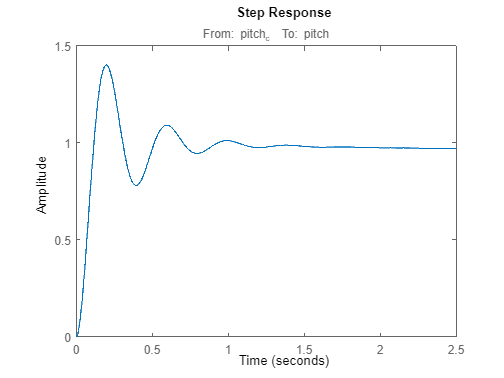

step(Gpitch)

stepinfo(Gpitch)

ans = struct with fields:
         RiseTime: 0.0800
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.7801
      SettlingMax: 1.4016
        Overshoot: 40.1602
       Undershoot: 0
             Peak: 1.4016
         PeakTime: 0.1950


# TECS Analysis

GTECS = linearize('TECSHarness');
GTECS.InputName = {'Hc','Vc'};
GTECS.OutputName = {'H','V','theta'}

GTECS =
 
  A = 
                  elevator_CA   elevator_CA             u             v             w            Ze             p             q             r           phi         theta  TAS_dem_prev   vel_dot_lpf  STEdot_error  integTHR_sta       integKE   integSEBdot    error_last   target_last    integrator
   elevator_CA              0             0      -0.06414    -8.093e-30       -0.0031        0.0966             0             0             0             0             0       0.06422             0      0.002455             1             0             0             0             0             0
   elevator_CA       -0.09881      -0.01379        -0.172    -6.278e-28       -0.4918       -0.1643    -2.653e-28          8.33     -1.55e-26    -1.955e-26         284.2        0.2212        0.1531     1.661e-07     6.765e-05      -0.03849      -0.03849       -0.1321      -0.05359       -0.9226
   u                 0.001608     7.699e-06        0.9957     2.748e-29       0.01137      0.00

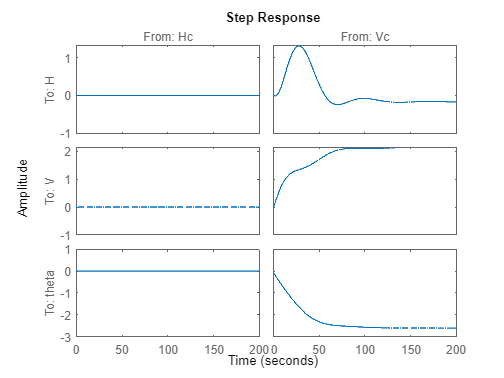

step(GTECS)

damp(GTECS)

                                                                                    
         Pole             Magnitude     Damping       Frequency      Time Constant  
                                                    (rad/seconds)      (seconds)    
                                                                                    
  1.00e+00                 1.00e+00    -1.00e+00       1.11e-14        -9.01e+13    
  9.99e-01                 9.99e-01     1.00e+00       4.56e-02         2.19e+01    
  9.99e-01 + 1.82e-03i     9.99e-01     3.66e-01       9.81e-02         2.78e+01    
  9.99e-01 - 1.82e-03i     9.99e-01     3.66e-01       9.81e-02         2.78e+01    
  9.97e-01                 9.97e-01     1.00e+00       1.33e-01         7.49e+00    
  1.00e+00                 1.00e+00    -1.00e+00       1.34e-01        -7.49e+00    
  9.94e-01 + 8.07e-04i     9.94e-01     9.92e-01       3.28e-01         3.07e+00    
  9.94e-01 - 8.07e-04i     9.94e-01     9.92e-01       3.28e-01  